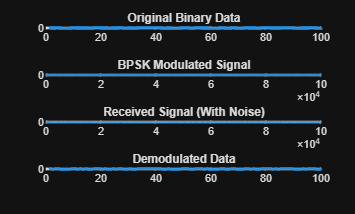

clc;
clear;
close all;

%% Parameters
N = 100;            % Number of bits
fs = 1000;          % Sampling frequency
Tb = 1;             % Bit duration
fc = 10;            % Carrier frequency
t = 0:1/fs:Tb-1/fs; % Time vector

%% Generate Binary Data
data = randi([0 1],1,N);

%% Polar Conversion
polar_data = 2*data - 1;    % 1 -> +1, 0 -> -1

%% Carrier Signal
carrier = cos(2*pi*fc*t);

%% BPSK Modulation
bpsk_signal = [];

for i = 1:N
    bpsk_signal = [bpsk_signal polar_data(i)*carrier];
end

%% Channel (Add Noise)
snr = 10;
rx_signal = awgn(bpsk_signal, snr, 'measured');

%% Coherent Demodulation
demod = [];
for i = 1:N
    segment = rx_signal((i-1)*length(t)+1 : i*length(t));
    product = segment .* carrier;
    decision = sum(product);
    
    if decision > 0
        demod = [demod 1];
    else
        demod = [demod 0];
    end
end

%% Plot Results
figure;

subplot(4,1,1)
stairs(data,'LineWidth',2)
title('Original Binary Data')
ylim([-0.5 1.5])

subplot(4,1,2)
plot(bpsk_signal)
title('BPSK Modulated Signal')

subplot(4,1,3)
plot(rx_signal)
title('Received Signal (With Noise)')

subplot(4,1,4)
stairs(demod,'LineWidth',2)
title('Demodulated Data')
ylim([-0.5 1.5])

BER = sum(data ~= demod)/N

BER = 0